# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to Thursday 22th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix 

Rm1 = Eaa2rotMat([0;0;1],90)

Rm1 =      0    -1     0
     1     0     0
     0     0     1


d1 = det(Rm1)

d1 = 1

- Compare the transpose and the inverse of the resulting matrix

Rm1T = Rm1'

Rm1T =      0     1     0
    -1     0     0
     0     0     1


Rm1Inverse = inv(Rm1)

Rm1Inverse =      0     1     0
    -1     0     0
     0     0     1


- Using the output matrix, transform a vector parallel to the axis of rotation. 

Vf = Rm1 * [0;0;6]

Vf =      0
     0
     6


What happens?

    *A vector parallel to the rotation axis can not be rotated any angle because the vector remains the same. If we imagine the vector as a cillinder, we would see how it rotates on its own central axis (the one that's normal to the top and bottom faces).*

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the escalar product between the original  vector and the transformed one.

Wf = Rm1 * [0;5;0]

Wf =     -5
     0
     0


 What you observe?

    *The rotation on a perpendicular vector makes, the components of it to change between them and changes its symbol too. Its value could change depending on the axis and angle introduced initially. In this case as the axis was [0,0,1]' and the angle 90º, the rotation affects this way.*

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5);

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100);

 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair theta-axis, (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

- Make a plot of the trace that you have obtained vs the theta angle. Explain what you observe.

               * Explanation Here:*

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Comment here and include code if you need it.*

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

*Solution here : *

## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( , , )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ ( , , )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ ( , , )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8


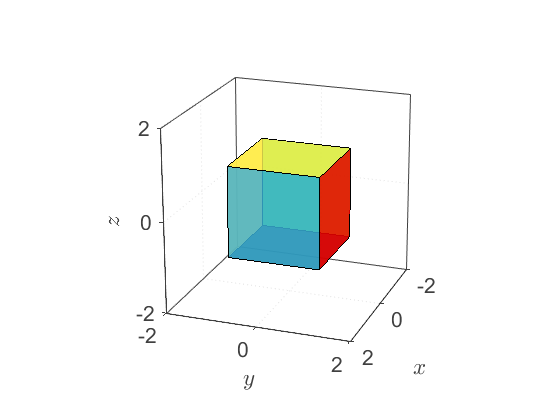

R = eye(3);
M_mod = (R*M')';
Cubeplot(M_mod);

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

- Compare the transpose and the inverse of the resulting matrix

**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented. You can set phi = 0 if you need it.

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.